# Matias Hiillos

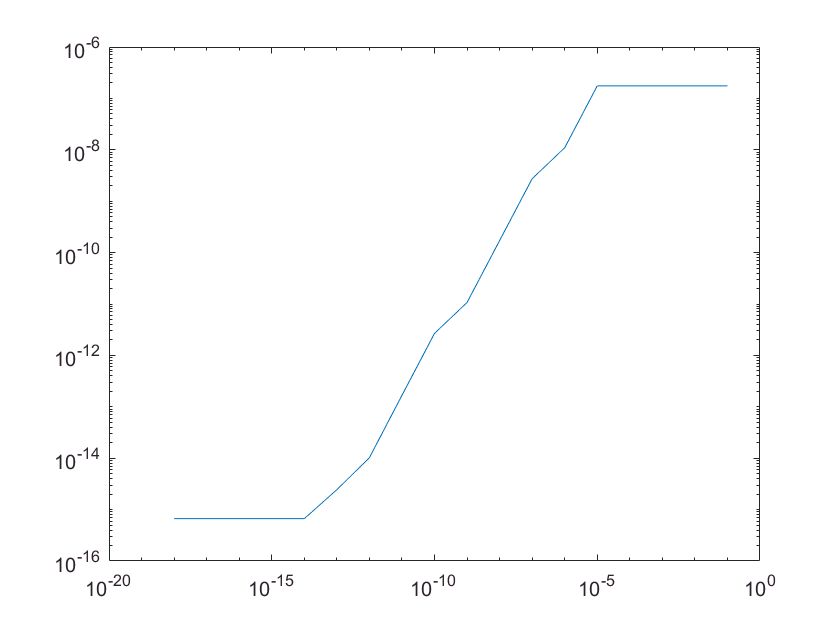

f = @(x) log(x)./(x-1);
y3 = 1:18;
for k = 1:18
    int_f = integral(f,0,1,'AbsTol',10^(-k),'RelTol',10^(-k));
    y3(k) = int_f;
end
err3 = pi^2/6 - y3;
k = 1:18;
tolerance = 10.^(-k);
loglog(tolerance,abs(err3))